# Respuesta en frecuencia

## Ploteo respuesta en frecuencia

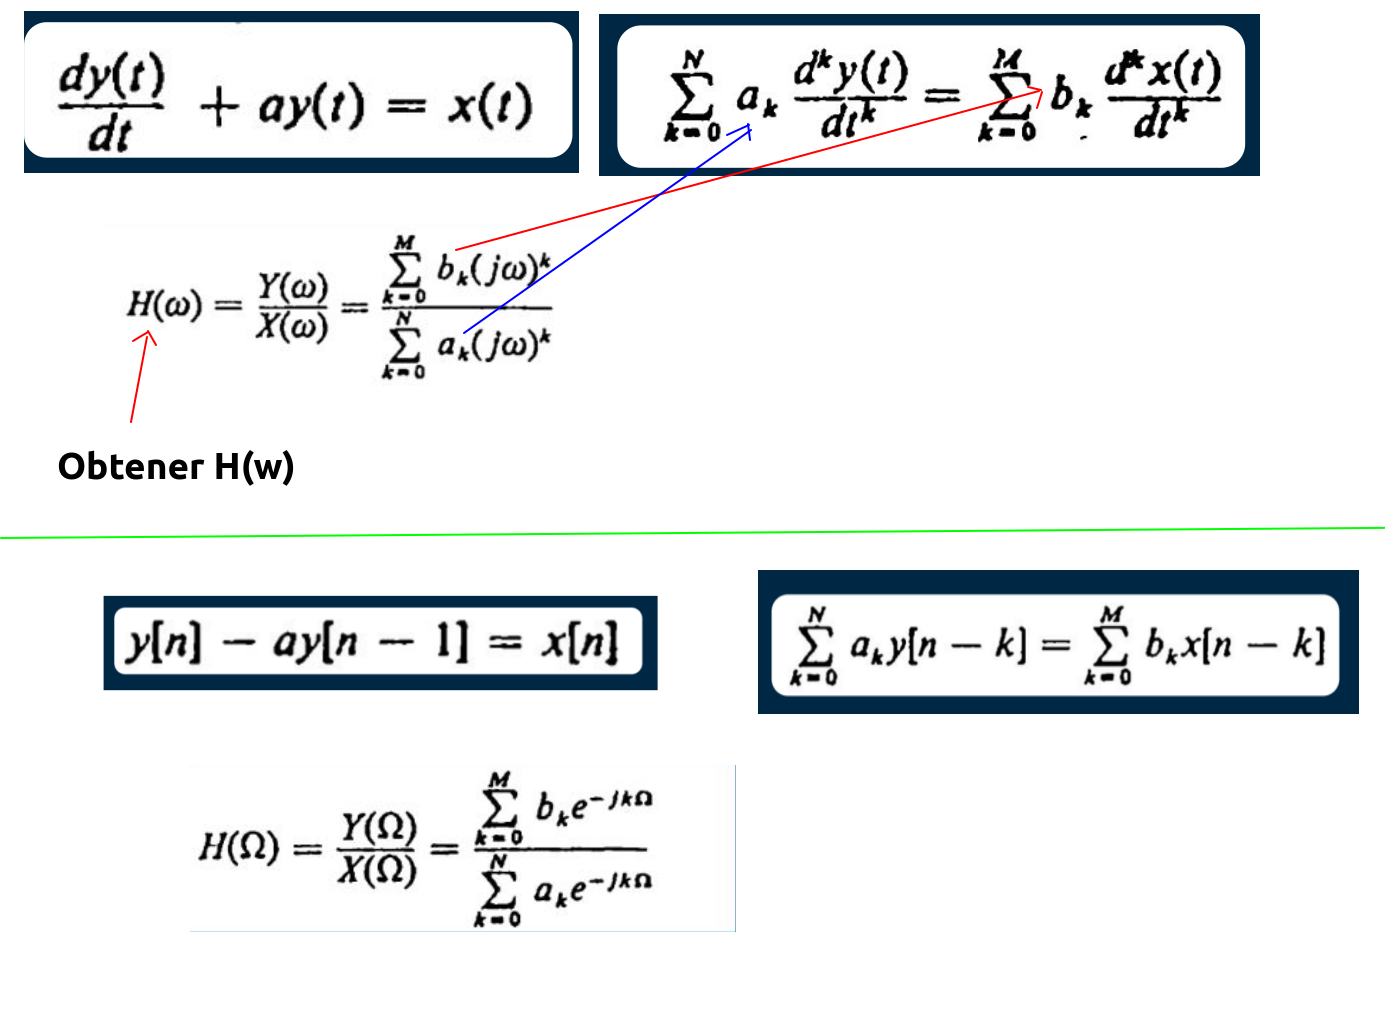

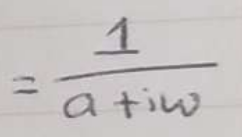 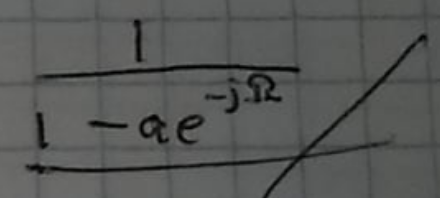

H(w)_Diferencial // H(w)_Diferencias

Uno es propiedad de Erik y otro es de Adrián.

## Diferencial


syms omega
a=3;
H=1/(a+1i*omega)

$$H = \frac{1}{3+\omega \,\mathrm{i}}$$

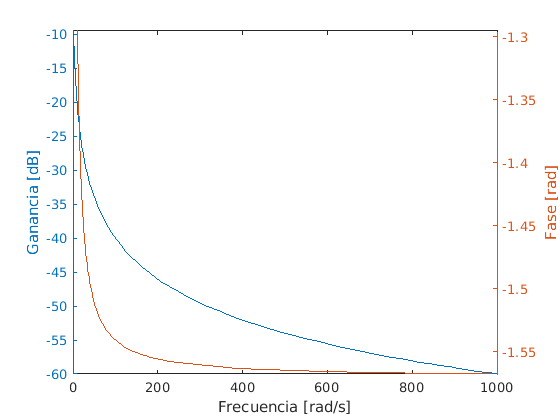


figure
%Magnitud db
yyaxis left 
fplot(20*log10(abs(H)),[0 1000])
ylabel("Ganancia [dB]")

%Fase
yyaxis right
fplot(angle(H),[0.1 1000])
ylabel("Fase [rad]")

xlabel("Frecuencia [rad/s]")

%set(gca,'XScale','log')


## Diferencias

%Diferencial
syms omega
a=3;
H=1/(1-a*exp(-1i*omega))

$$H = -\frac{1}{3\,{\mathrm{e}}^{-\omega \,\mathrm{i}}-1}$$

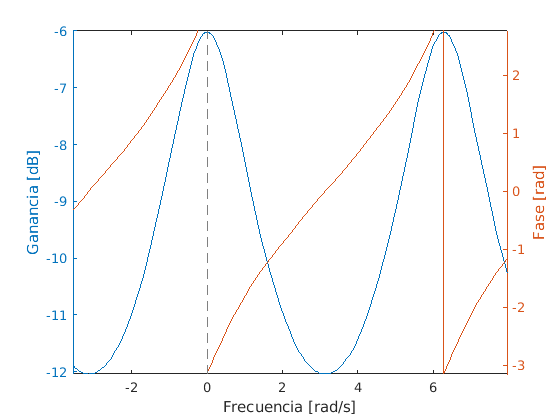

span=[-4*pi 4*pi];

figure
%Magnitud db
yyaxis left 
fplot(20*log10(abs(H)),span)
ylabel("Ganancia [dB]")

%Fase
yyaxis right
fplot(angle(H),span)
ylabel("Fase [rad]")

xlabel("Frecuencia [rad/s]")

%set(gca,'XScale','log')


## Funcion transferencia filtro pasa bajos

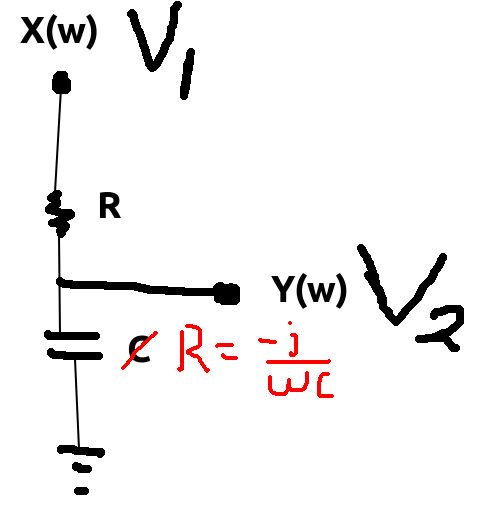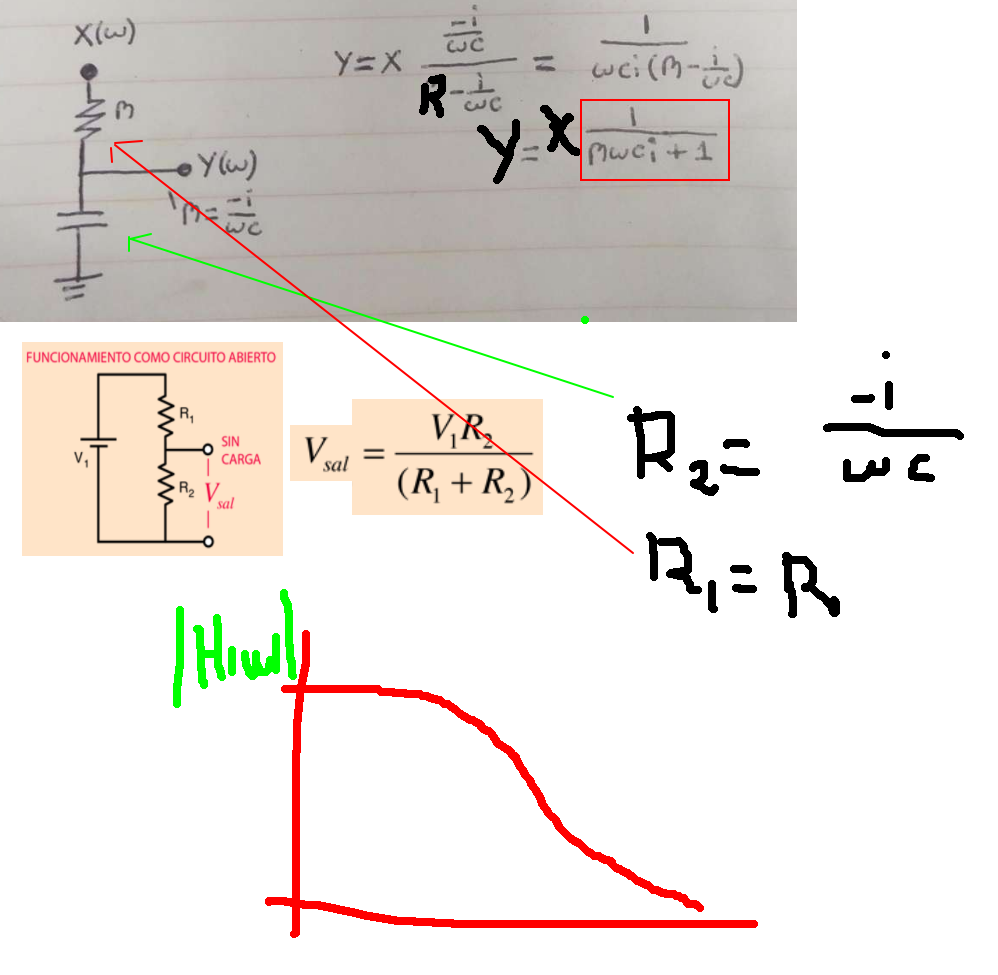

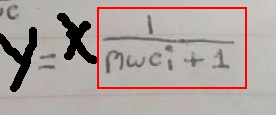 Propiedad de Adrian

clear
syms f
C=220E-12%[F]

C = 2.2000e-10

R=10E3%[ohm]

R = 10000


%Respuesta en frecuencia
H=1/(R*C*(2*pi*f)*1i+1)

$$H = \frac{1}{1+\frac{5194603131156609\,\pi \,f\,\mathrm{i}}{1180591620717411303424}}$$



span=[0.1 1E6]

span = 	1.0e+06 *

    0.0000    1.0000


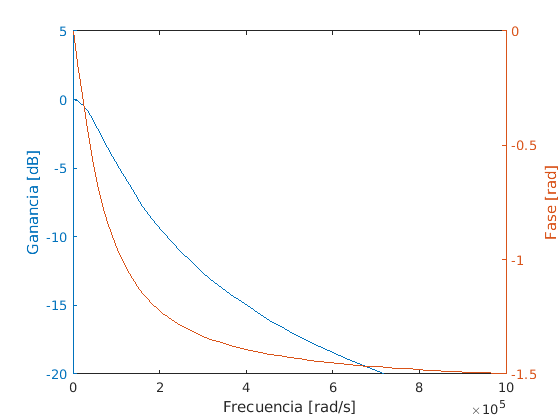


figure
%Magnitud db
yyaxis left 
fplot(20*log10(abs(H)),span)
ylabel("Ganancia [dB]")
ylim([-20 5])

%Fase
yyaxis right
fplot(angle(H),span)
ylabel("Fase [rad]")
xlabel("Frecuencia [rad/s]")